# **PESTools - Example 006 - Testing the file loaders**

This example shows how to perform common operations on ARPES data using the functions of the MATools and PESTools toolkit.

For a more in-depth explanation of potential in- and output of those functions, consult the UserGuide.

close all; clear all;
pp          = plot_props();
data_path   = 'D:\OneDrive\PCC_MS_Project\00_Software_Library\ADRESSTools\ADRESSTools_Basil\PESTools_PCC\Examples\Example_Data\';

# **Creating artificial data structures**

temp_arpes_data = create_arpes_data()

temp_arpes_data = struct with fields:
    FileName: ''
      H5file: ''
        Type: "Eb(k)"
       index: 1
        meta: [1×1 struct]
    raw_data: []
     raw_tht: []
      raw_eb: []
         deb: []
          hv: []
         dhv: []
        tltM: []
        thtM: []
        Temp: []

temp_pes_data   = create_pes_data()

temp_pes_data = struct with fields:
    FileName: ''
      H5file: ''
        Type: "PES"
          hv: []
        xdat: []
        ydat: []

# **SIS Beamline, ULTRA: **Testing Eb(kx) data processing

**(A) Loading in the ARPES data files**

% Loading in the data files
file_names      = {...
    'SIS_GXCut_59_Cp_0000.h5',...
    };
arpes_dat = cell(1,length(file_names));
for i = 1:length(file_names); arpes_dat{i} = load_sis_data(file_names{i}, data_path); end

Loading in SIS data...


- Data slice formation
- Re-mapping


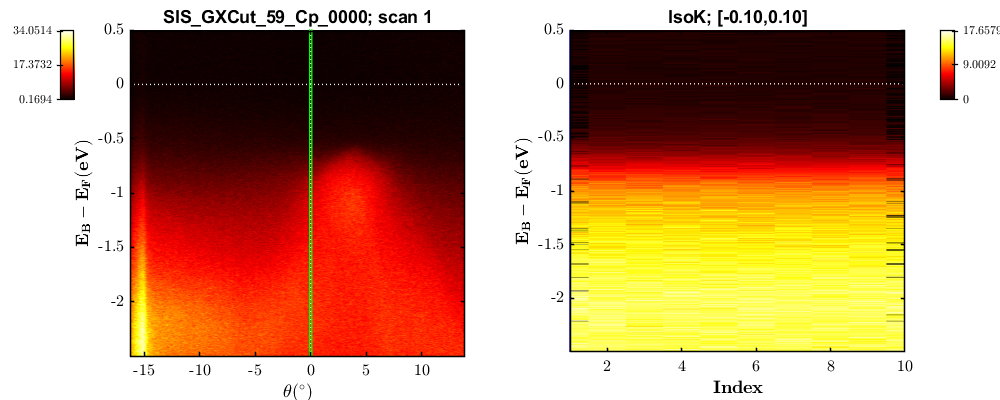

view_arpes_data(arpes_dat{1});

% Cross-correlating the data files
for i = 1:length(arpes_dat); arpes_dat{i} = xcorr_scans(arpes_dat{i}); end

- Correlating scans
Scan = 2: Offset = 0.006
Scan = 3: Offset = 0.009
Scan = 4: Offset = 0.003
Scan = 5: Offset = -0.003
Scan = 6: Offset = 0
Scan = 7: Offset = 0
Scan = 8: Offset = 0.003
Scan = 9: Offset = -0.003
Scan = 10: Offset = 0.003


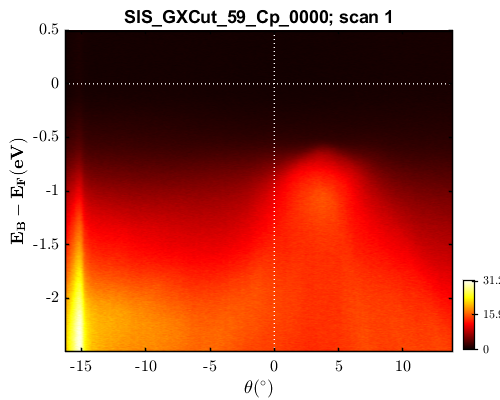

view_arpes_data(arpes_dat{1});

**(B) Loading in the Fermi-Edge reference files**

% Loading in the data files
file_names_ef      = {...
    'SIS_Au_59eV_0000.h5',...
    };
arpes_ref = cell(1,length(file_names_ef));
for i = 1:length(file_names_ef); arpes_ref{i} = load_sis_data(file_names_ef{i}, data_path); end

Loading in SIS data...


- Data slice formation
- Re-mapping


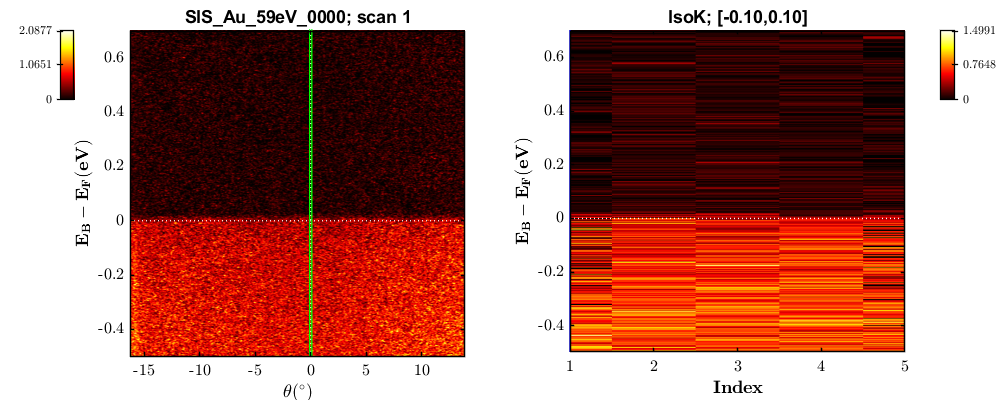

view_arpes_data(arpes_ref{1});

% Cross-correlating the reference files to get a good estimate on EF
for i = 1:length(arpes_ref); arpes_ref{i} = xcorr_scans(arpes_ref{i}); end

- Correlating scans
Scan = 2: Offset = -0.002
Scan = 3: Offset = 0.008
Scan = 4: Offset = -0.002
Scan = 5: Offset = 0


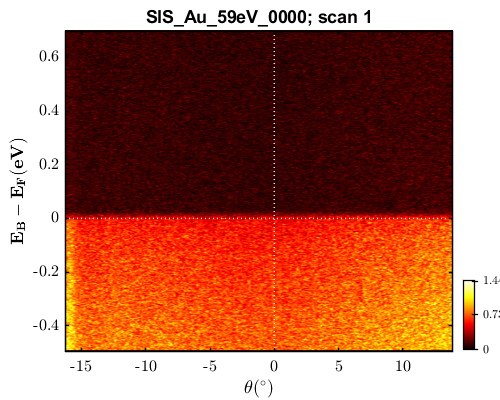

view_arpes_data(arpes_ref{1});

**(C) Binding energy alignment to the reference data**

% (1) COARSE ALIGNMENT TO THE EDGE
% -- Coarse alignment of the energy
alignType   = "align2ref";      % either "global", "global shift via scan", "scans", "ref", "ref (per channel)", "fit2ref"
scan_indxs	= [];               % for "global" or "ref" it is empty []. For "scans", it defines the scan indices to perform alignment on.
eWin        = 0.0;              % approximate EF position. Can be a single, constant value. If a vector, it linear interpolates estimates between [firstEF, endEF].
dEWin       = 4.00;             % can be empty []. Single, constant value that defines the width of the EF.
dESmooth    = [];               % can be empty []. Single, constant value that defines Gaussian pre-smoothing energy width.
feat        = 'edge';           % either 'edge' or 'peak'. defines the feature to align as a 'peak' instead of the default Fermi 'edge'.
align_args  = {alignType, scan_indxs, eWin, dEWin, dESmooth, feat};
for i = 1:length(arpes_dat)
    arpes_dat{i}  = align_energy(arpes_dat{i}, align_args, arpes_ref{i}); 
    arpes_ref{i}.raw_eb = arpes_ref{i}.raw_eb - arpes_dat{i}.eb_shifts{1};
end

- EF alignment


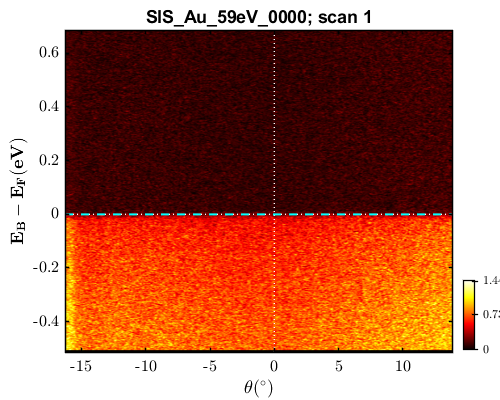

view_arpes_data(arpes_ref{1}); line([-1e3, 1e3], [0, 0], 'color', 'c', 'linewidth', 1.5, 'linestyle', '--'); 

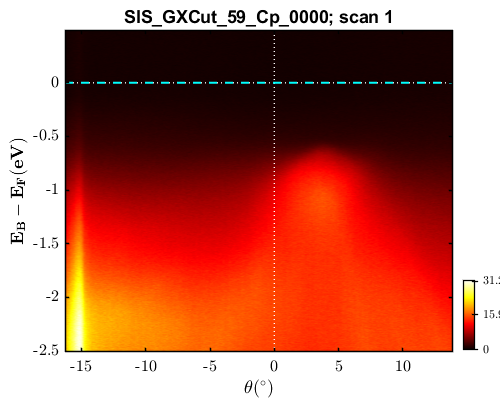

% (2) FITTING TO THE FDD WITH FINE ALIGNMENT
alignType   = "fit2ef";        % either "global", "global shift via scan", "scans", "ref", "ref (per channel)", "fit2ref"
scan_indxs	= [];              % for "global" or "ref" it is empty []. For "scans", it defines the scan indices to perform alignment on.
eWin        = 0.00;            % approximate EF position. Can be a single, constant value. If a vector, it linear interpolates estimates between [firstEF, endEF].
dEWin       = 0.50;            % can be empty []. Single, constant value that defines the width of the EF.
dESmooth    = [];              % can be empty []. Single, constant value that defines Gaussian pre-smoothing energy width.
feat        = 'edge';          % either 'edge' or 'peak'. defines the feature to align as a 'peak' instead of the default Fermi 'edge'.
align_args  = {alignType, scan_indxs, eWin, dEWin, dESmooth, feat};
for i = 1:length(arpes_dat)
    arpes_dat{i}  = align_energy(arpes_dat{i}, align_args, arpes_ref{i}); 
end
view_arpes_data(arpes_dat{1});
line([-1e3, 1e3], [0, 0], 'color', 'c', 'linewidth', 1.5, 'linestyle', '--');

**(D) Background subtraction and intensity normalisation**

bgrdType    = "AngleInt-clip";   % either "angle/kx-int (fixed edc)", "angle/kx-int (fixed edc) (per channel)", "angle/kx-int (fixed mean)", "angle/kx-int (moving mean)", "none"
bgrdWin     = [];                  % EDC angle range to integrate over to extract ISubtr
bgrdScale   = 0.25;                         % scale coefficient to subtract (Data - intScale * ISubtr)
bgrdSmooth  = 25;                          % single, constant value that determine presmoothing of data to extract background. 
normType    = "max-each";           % "max (all scans)", "max (each scan)", "mean (each scan)", "none"
bgrd_args   = {bgrdType, bgrdWin, bgrdScale, bgrdSmooth, normType}; 
for i = 1:length(arpes_dat)
    arpes_dat{i} = bgrd_subtr_data(arpes_dat{i}, bgrd_args); 
end

- Angle integrating


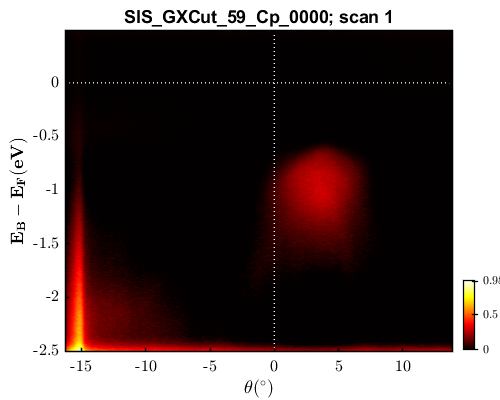

view_arpes_data(arpes_dat{1});

**(E) Wave-vector conversions**

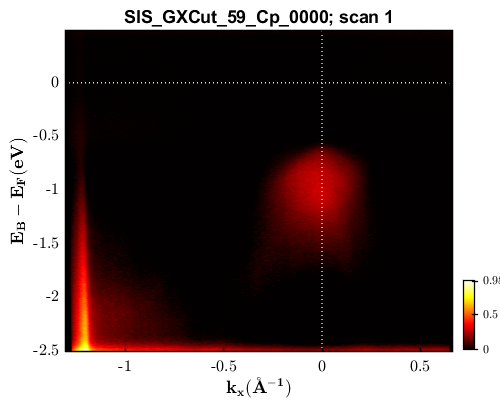

eB_ref      = 0;            % single, constant value of the binding energy at the refernece point.
kx_ref      = 0;            % single, constant value of the wave-vector value at the reference point.
thtA_ref    = 3.798;         % single, constant value of the tht angle value at the reference point.
v000        = 12.57;        % single, constant value of the inner potential. Tune to make sure spacing of Gamma points is correct. Default is 12.57.
kconv_args  = {eB_ref, kx_ref, thtA_ref, v000}; 
for i = 1:length(arpes_dat)
    arpes_dat{i} = convert_to_k(arpes_dat{i}, kconv_args);
    % -- custom shift to centralise kx
    arpes_dat{i}.kx = arpes_dat{i}.kx;
end
view_arpes_data(arpes_dat{1});

**(F) Cropping the ARPES data**

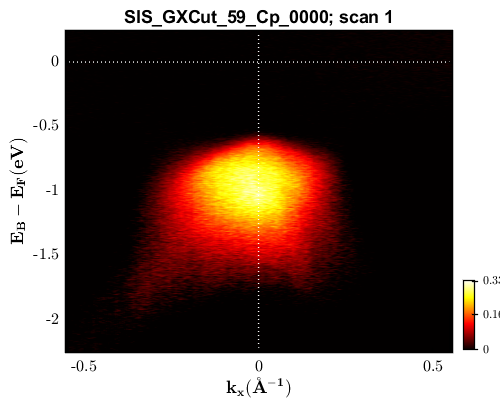

ans = struct with fields:
       FileName: 'SIS_GXCut_59_Cp_0000'
         H5path: 'D:\OneDrive\PCC_MS_Project\00_Software_Library\ADRESSTools\ADRESSTools_Basil\PESTools_PCC\Examples\Example_Data\'
         H5file: 'SIS_GXCut_59_Cp_0000.h5'
           Type: "Eb(k)"
          index: 1
       raw_data: [1001×684 double]
        raw_tht: [1×684 double]
         raw_eb: [1001×1 double]
             hv: 59.0024
           tltM: 0.7987
           thtM: -0.0142
           Temp: 28.4981
           meta: [1×1 struct]
      eb_shifts: {[0.0152]  [-0.0058]}
    eb_ref_file: 'SIS_Au_59eV_0000'
             eb: [834×383 double]
            tht: [834×383 double]
           data: [834×383 double]
      surfNormX: -3.3500
             kx: [834×383 double]
             ky: 0.0516
             kz: 4.2648

xLims       = [-0.55, 0.55];    % x-axis limits to crop (if empty like [], does not crop this axis)
yLims       = [-2.25, 0.25];     % y-axis limits to crop (if empty like [], does not crop this axis)
zLims       = [];               % z-axis limits to crop (if empty like [], does not crop this axis)
for i = 1:length(arpes_dat) 
    arpes_dat{i} = data_crop3D(arpes_dat{i}, xLims, yLims, zLims);
    view_arpes_data(arpes_dat{i}); arpes_dat{i}
end

**(G) Extracting a series of EDC cuts**

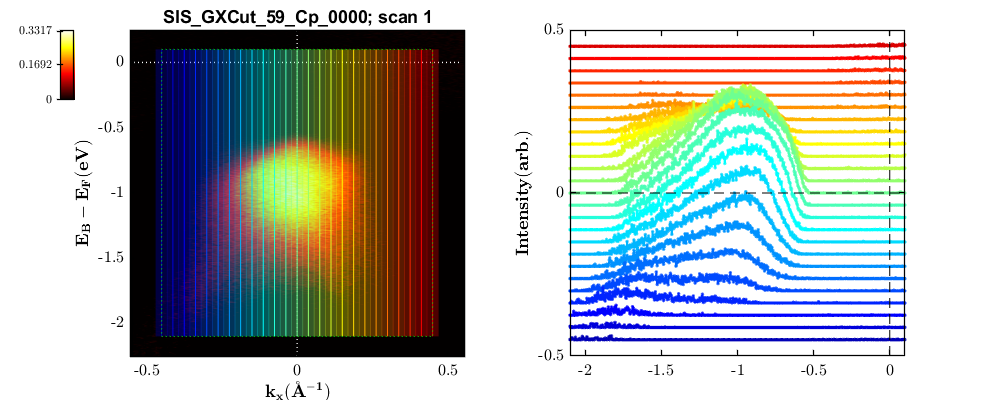

cutStr_03 = struct with fields:
    isocut_args: {1×6 cell}
         xField: "kx"
       FileName: 'SIS_GXCut_59_Cp_0000'
           Type: "Eb(k)"
        IsoType: "EDC"
         IsoVal: [1×25 double]
         IsoWin: [-0.0200 0.0200]
         IsoNum: 25
           XCut: {1×25 cell}
           DCut: {1×25 cell}

nFrame          = 1;                    % Scan number to be cut
isocutType          = "EDC";            % Type of line profile to extract. "EDC" (vertical) or "MDC" (horizontal)
isocutWin           = 0.02;             % single, constant valueof the integration window.
isocutXLims         = [-0.45, 0.45];    % 1x2 vector which gives the x-axis limits of the train [minX, maxX]
isocutYLims         = [-2.1, 0.1];      % 1x2 vector which gives the y-axis limits of the train [minY, maxY]
isocutN             = 25;               % single, constant value that determines the total number of line profiles to extract
isocut_args         = {nFrame, isocutType, isocutWin, isocutXLims, isocutYLims, isocutN};
plot_result         = 1;                % Show a plot of the data that is extracted. if 1, it will make the plot, if 0 it won't.
[cutStr_03, ~]      = extract_isoCut_series(arpes_dat{1}, isocut_args, plot_result); cutStr_03

# **SIS Beamline, ULTRA:** Testing PES Data Processing

**(A) Loading in the PES data files**

% Explicitely defining the file-names
file_names      = {...
    'SIS_XPS_750eV_0000.h5',...
    };
% Load in the data
PES_dat = cell(1,length(file_names));
for i = 1:length(file_names); PES_dat{i} = load_sis_data(file_names{i}, data_path); end

Loading in SIS data...


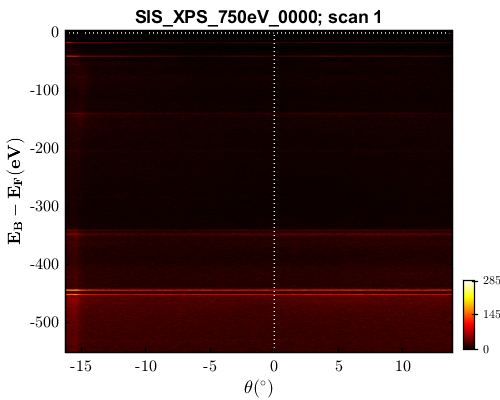

ans = struct with fields:
    FileName: 'SIS_XPS_750eV_0000'
      H5path: 'D:\OneDrive\PCC_MS_Project\00_Software_Library\ADRESSTools\ADRESSTools_Basil\PESTools_PCC\Examples\Example_Data\'
      H5file: 'SIS_XPS_750eV_0000.h5'
        Type: "Eb(k)"
       index: 1
    raw_data: [5551×684 double]
     raw_tht: [1×684 double]
      raw_eb: [5551×1 double]
          hv: 749.9943
        tltM: 0.7987
        thtM: -0.0142
        Temp: 31.2782
        meta: [1×1 struct]

view_arpes_data(PES_dat{1}); PES_dat{1}

**(B) Loading in the Fermi edge reference via gold / copper**

% Explicitely defining the file-names
file_names_ef      = {...
    'SIS_Au_750eV_0000.h5',...
    };
% Load in the data
PES_ref = cell(1,length(file_names_ef));
for i = 1:length(file_names_ef); PES_ref{i} = load_sis_data(file_names_ef{i}, data_path); end

Loading in SIS data...


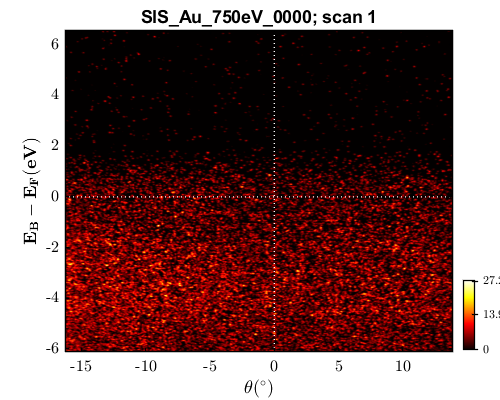

ans = struct with fields:
    FileName: 'SIS_Au_750eV_0000'
      H5path: 'D:\OneDrive\PCC_MS_Project\00_Software_Library\ADRESSTools\ADRESSTools_Basil\PESTools_PCC\Examples\Example_Data\'
      H5file: 'SIS_Au_750eV_0000.h5'
        Type: "Eb(k)"
       index: 1
    raw_data: [895×684 double]
     raw_tht: [1×684 double]
      raw_eb: [895×1 double]
          hv: 749.9795
        tltM: 0.7987
        thtM: -0.0142
        Temp: 31.0978
        meta: [1×1 struct]

view_arpes_data(PES_ref{1}); PES_ref{1}

**(C) Binding energy alignment to the reference data**

- EF alignment


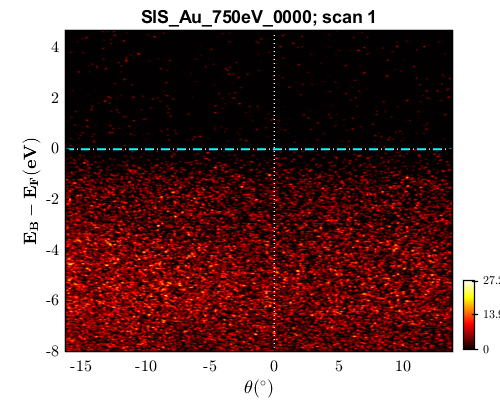

% (1) AUTOMATIC COARSE ALIGNMENT TO THE EDGE OF THE REFERENCE
% -- Coarse alignment of the energy
alignType   = "align2ref";        % either "global", "global shift via scan", "scans", "ref", "ref (per channel)", "fit2ref"
scan_indxs	= [];               % for "global" or "ref" it is empty []. For "scans", it defines the scan indices to perform alignment on.
eWin        = 0.00;                % approximate EF position. Can be a single, constant value. If a vector, it linear interpolates estimates between [firstEF, endEF].
dEWin       = 4.00;              % can be empty []. Single, constant value that defines the width of the EF.
dESmooth    = [];               % can be empty []. Single, constant value that defines Gaussian pre-smoothing energy width.
feat        = 'edge';           % either 'edge' or 'peak'. defines the feature to align as a 'peak' instead of the default Fermi 'edge'.
align_args  = {alignType, scan_indxs, eWin, dEWin, dESmooth, feat};
for i = 1:length(PES_dat)
    PES_dat{i}  = align_energy(PES_dat{i}, align_args, PES_ref{i}); 
    PES_ref{i}.raw_eb = PES_ref{i}.raw_eb - PES_dat{i}.eb_shifts{1};
    view_arpes_data(PES_ref{i});
    line([-1e3, 1e3], [0, 0], 'color', 'c', 'linewidth', 1.5, 'linestyle', '--'); 
end

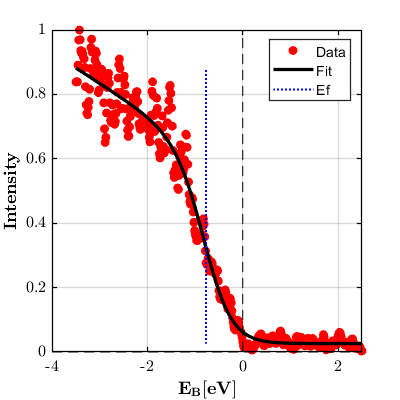

% (2) FITTING TO THE FDD WITH FINE ALIGNMENT
alignType   = "fit2ef-75%";        % either "global", "global shift via scan", "scans", "ref", "ref (per channel)", "fit2ref"
scan_indxs	= [];               % for "global" or "ref" it is empty []. For "scans", it defines the scan indices to perform alignment on.
eWin        = -0.5;                % approximate EF position. Can be a single, constant value. If a vector, it linear interpolates estimates between [firstEF, endEF].
dEWin       = 3.0;              % can be empty []. Single, constant value that defines the width of the EF.
dESmooth    = [];               % can be empty []. Single, constant value that defines Gaussian pre-smoothing energy width.
feat        = 'edge';           % either 'edge' or 'peak'. defines the feature to align as a 'peak' instead of the default Fermi 'edge'.
align_args  = {alignType, scan_indxs, eWin, dEWin, dESmooth, feat};
for i = 1:length(PES_dat)
    PES_dat{i}  = align_energy(PES_dat{i}, align_args, PES_ref{i}, 1); 
end

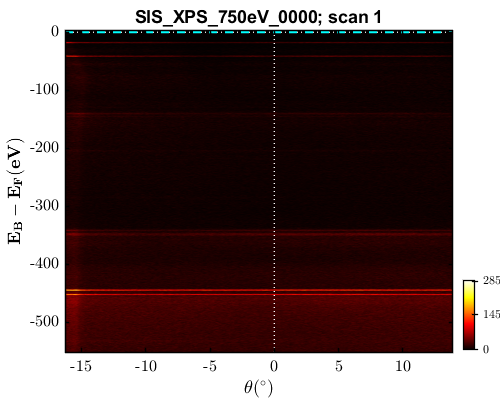

view_arpes_data(PES_dat{1});
line([-1e3, 1e3], [0, 0], 'color', 'c', 'linewidth', 1.5, 'linestyle', '--'); 

**(D) Extract the PES data by angle-integrating the ARPES spectrum**

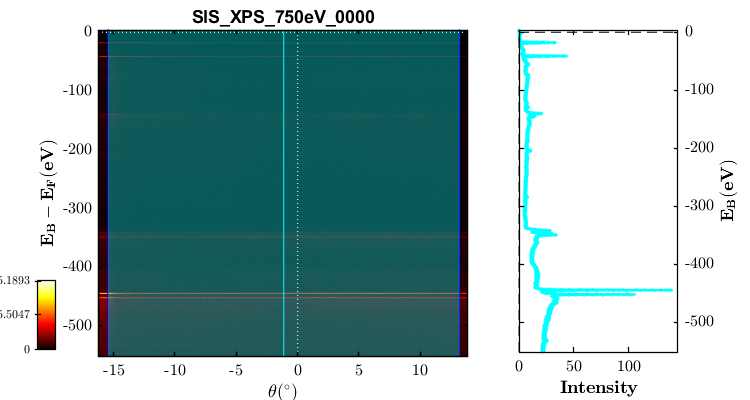

cutWin          = 0.95*[min(PES_dat{1}.tht(:)), max(PES_dat{1}.tht(:))];    % Integration window of the cut to be made.
cutN            = 1;                                                        % Single, constant value that determines the total number of line profiles to extract
xps_args        = {cutWin, cutN};
for i = 1:length(PES_dat)
    [PES_dat{i}, ~]     = pes_extract_data(PES_dat{i}, xps_args);
end

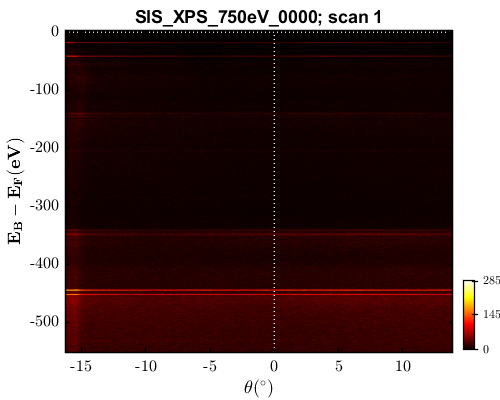

if length(PES_dat{i}) > 1; PES_dat = [PES_dat{:}]; end
view_arpes_data(PES_dat{1});

**(E) Normalisation of the PES spectrum**

ans = "xval = -444.50 eV, yval = 138.92"

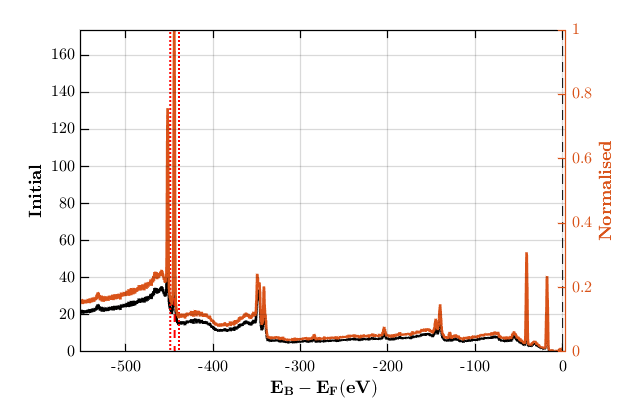

eWin            = -444;        % approximate Eb position of a peak in the spectrum to normalise to.
dEWin           = 5;          % can be empty []. Single, constant value that defines the width of the approximate Eb position
norm_args    = {eWin, dEWin};
for i = 1:length(PES_dat)
    PES_dat{i}.ydat = pes_norm2peak(PES_dat{i}.xdat, PES_dat{i}.ydat, norm_args, 1);
end

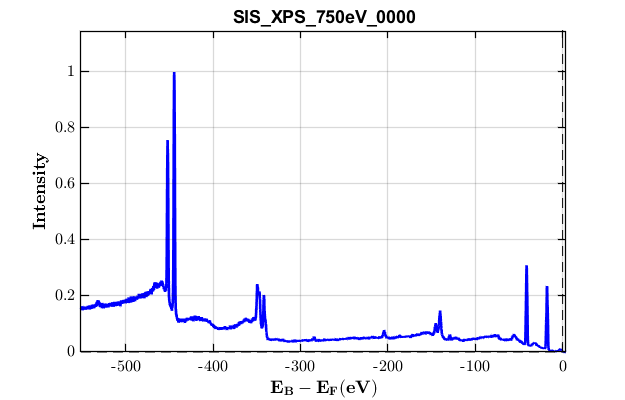

view_pes_data(PES_dat{1});

**(F) Final data structure after all the processing**

view_pes_data(PES_dat); PES_dat{1}

ans = struct with fields:
       FileName: 'SIS_XPS_750eV_0000'
         H5path: 'D:\OneDrive\PCC_MS_Project\00_Software_Library\ADRESSTools\ADRESSTools_Basil\PESTools_PCC\Examples\Example_Data\'
         H5file: 'SIS_XPS_750eV_0000.h5'
           Type: "Eb(k)"
          index: 1
       raw_data: [5551×684 double]
        raw_tht: [1×684 double]
         raw_eb: [5551×1 double]
             hv: 749.9943
           tltM: 0.7987
           thtM: -0.0142
           Temp: 31.2782
           meta: [1×1 struct]
      eb_shifts: {[1.8807]  [-0.7694]}
    eb_ref_file: 'SIS_Au_750eV_0000'
             eb: [5551×684 double]
            tht: [5551×684 double]
        IsoType: "XPS"
       pes_args: {[-15.4615 13.1957]  [1]}
         cutWin: [-15.4615 13.1957]
           cutN: 1
           xdat: [5551×1 double]
           ydat: [5551×1 double]

Loading in SIS data...


arpes_kxkz = struct with fields:
    FileName: 'SIS_kz_21_141_Cp_0000'
      H5path: 'D:\OneDrive\PCC_MS_Project\00_Software_Library\ADRESSTools\ADRESSTools_Basil\PESTools_PCC\Examples\Example_Data\'
      H5file: 'SIS_kz_21_141_Cp_0000.h5'
        Type: "Eb(kx,kz)"
       index: [1×61 double]
    raw_data: [895×684×61 double]
     raw_tht: [1×684 double]
      raw_eb: [895×1 double]
          hv: [1×61 double]
        tltM: 0.7987
        thtM: -0.0142
        Temp: 25.8910
        meta: [1×1 struct]

- Data slice formation
- Re-mapping


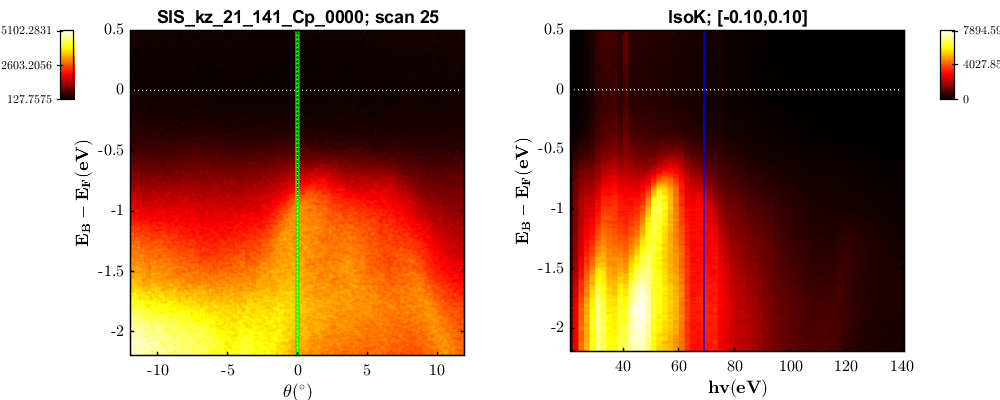

lgnd = {}; for i = 1:length(PES_dat); lgnd{end+1} = string(PES_dat{i}.hv) + " eV"; end
legend(lgnd,'Location','best'); title(sprintf("XPS Survey at SIS"), 'interpreter', 'none');

# **SIS Beamline, ULTRA: **Testing Eb(kx,kz) data processing

**(A) Loading in the data**

% -- Make sure you extract the data first from its compressed form, in order to load it in
arpes_kxkz     = load_sis_data('SIS_kz_21_141_Cp_0000.h5', data_path); arpes_kxkz

**(B) Cropping the data**

xLims       = [-12, 12];          % x-axis limits to crop (if empty like [], does not crop this axis)
yLims       = [-2.2,0.5];       % y-axis limits to crop (if empty like [], does not crop this axis)
zLims       = [];               % z-axis limits to crop (if empty like [], does not crop this axis)
arpes_kxkz     = data_crop3D(arpes_kxkz, xLims, yLims, zLims);
nFrame          = 25;               % Scan number to view
sliceType       = "IsoK";           % "IsoE" or "IsoK"
sliceWin        = [-0.1, 0.1];      % Window for the slice to be taken
remap           = 1;                % Remap the slice onto a square grid? 1 or 0
isoslice_args   = {nFrame, sliceType, sliceWin, remap};
view_arpes_data(arpes_kxkz, isoslice_args);